## **BÁO CÁO THỰC HÀNH LAB 1**

**Dữ liệu tương tự và số**

Họ và tên: Lê Hoàng Nam

MSSV: 21207246

Câu 1: Vẽ 2 chu kỳ đầu của tín hiệu

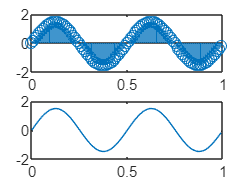

clear;clc
fs = 100; % sample frequency (Hz)
ts=1/fs;
t = 0:1/fs:1-1/fs;
x = (1.5)*sin(2*pi*2*t);
subplot(2,1,1)
stem(t,x)
subplot(2,1,2)
plot(t,x)

Câu 2: Thay đổi tần số lấy mẫu 1 Ks/s, tạo tín hiệu 100 Hz?

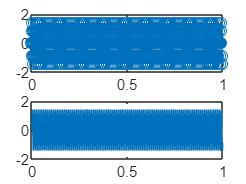

clear;clc
fs = 1000; % sample frequency (Hz)
ts=1/fs;
t = 0:1/fs:1-1/fs;
x = (1.5)*sin(2*pi*100*t);
subplot(2,1,1)
stem(t,x)
subplot(2,1,2)
plot(t,x)

Câu 3: Tạo tín hiệu tổng hợp gồm 3 tín hiệu: tín hiệu 1:50Hz, biên độ 1; tín hiệu 2: 100 Hz, biên độ 1.5; tín hiệu 3: 150 Hz, biên độ 0.5. 

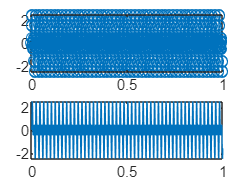

clear;clc
fs = 1000; % sample frequency (Hz)
ts=1/fs;
t = 0:1/fs:1-1/fs;
x = (1.5)*sin(2*pi*100*t) + sin(2*pi*50*t) + 0.5*sin(2*pi*150*t);
subplot(2,1,1)
stem(t,x)
subplot(2,1,2)
plot(t,x)

Câu 4: Vẽ phổ tín hiệu ở câu 3.

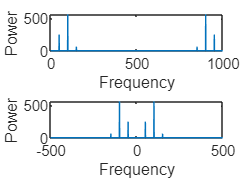

y = fft(x); %
n = length(x); % number of samples
f = (0:n-1)*(fs/n); % frequency range
power = abs(y).^2/n; % power of the DFT
figure (2)
subplot(2,1,1)
plot(f,power)
xlabel('Frequency')
ylabel('Power')
y0 = fftshift(y); % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n; % 0-centered power

subplot(2,1,2)
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')

Câu 5: Tạo nhiễu để có SNR=10dB và 20 dB.

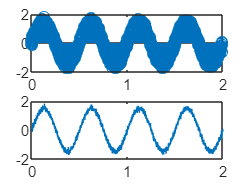

%clear;clc
fs = 1000; % sample frequency (Hz)
ts=1/fs;
t = 0:1/fs:2-1/fs;
x = (1.5)*sin(2*pi*2*t);
n = length(x); % number of samples
noise=0.106*randn([1,n]); %10dB = 0.3354; 20dB = 0.106
x=x+noise;
subplot(2,1,1)
stem(t,x)
subplot(2,1,2)
plot(t,x)

Câu 1: Xác định tốc độ bit, tốc baud?

- Tốc độ bit: 100 bps

- Tốc độ baud: 50 baud/s

Câu 2: Tạo dữ liệu có tốc độ bit 10Kbps?

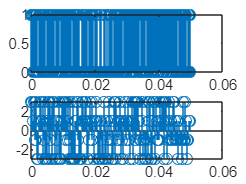

clear;clc
data = randi([0 1],1,10);
data_re=reshape(data,2,[]);
data_map= bi2de(data_re','left-msb')';
s=pammod(data_map,4);
stem(real(s));
fb=10000;
t=0:1/fb:0.05-1/fb;
M=4;
fbaud=fb/log2(M);
data = randi([0 1],1,length(t));

figure (1)
subplot(2,1,1)
stem(t,data)
data_re=reshape(data,2,[]);
data_map= bi2de(data_re','left-msb')';
s=pammod(data_map,M);

subplot(2,1,2)
tsym=0:1/fbaud:0.05-1/fbaud;
stem(tsym,real(s))

Câu 1: Cho biết ý nghĩa của “logical(dec2bin(x, 8) - '0')”?

- "x" là mã ASCII của các ký tự có trong file Test.txt.

- Hàm "dec2bin" chuyển giá trị ASCII của ký tự ở dạng thập phân sang dạng nhị phân, thêm 1 bit "0" để thành 8-bit.

- Hàm "logical" chuyển các giá trị vừa có được về dạng logic (0, 1).

Câu 2: Thực hiện tính và so sánh với kết quả?

clear;clc
fid = fopen('Test.txt');
x=fread(fid,'*char');
binvecc = logical(dec2bin(x, 8) - '0');
bit_steam=reshape(binvecc',1,[]);

   binvecc:

   0   1   0   0   1   0   0   0 - 72 - H

   0   1   1   0   0   1   0   1 - 101 - e

   0   1   1   0   1   1   0   0 - 108 - l

   0   1   1   0   1   1   0   0 - 108 - l

   0   1   1   0   1   1   1   1 - 111 - 0

Câu 3: Nếu tốc độ ký tự là 10 Kbps thì tốc độ bit bao nhiêu?

- 10 000 x 8 = 80 000 (bps)

Câu 4: Cho biết giá trị pixel tương màu trắng?

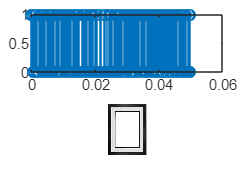

clear;clc
A = imread('Anh_300.jpg');
B=rgb2gray(A);
imshow(B);

- Giá trị pixel màu trắng: 255

Câu 5: Cho biết kích thước ảnh?

- Kích thước ảnh: 6.04 KB

Câu 6: Xác định tổng số bit của ảnh khi không nén?

- 300 x 233 x 3 x 8 = 1 677 600 bits